% setting
folder = 'C:\Users\bear\Desktop\figure 4';  
imagename = 'full_distance';
outname = 'idk';
extension = '.tif';
num_channel = 7;

multichannel = import4d(folder, imagename, extension, num_channel);

Finished importing channel 1
Finished importing channel 2
Finished importing channel 3
Finished importing channel 4
Finished importing channel 5
Finished importing channel 6
Finished importing channel 7


central = multichannel(:,:,:,3);
portal = multichannel(:,:,:,4);
% central_distance = multichannel(:,:,:,5);
% portal_distance = multichannel(:,:,:,6);

% refine mask
se_sphere = strel('sphere', 5);
binary_clean = imdilate(central, se_sphere);
binary_clean = imdilate(binary_clean, se_sphere);
binary_clean = imdilate(binary_clean, se_sphere);
binary_clean = imerode(binary_clean, se_sphere);
binary_clean = imerode(binary_clean, se_sphere);
binary_clean = imerode(binary_clean, strel('sphere', 1));
binary_clean = modefilt(binary_clean, [5 5 5]);
binary_clean = modefilt(binary_clean, [5 5 5]);

% export some temp things
temp = binary_clean;
temp = temp * 255;
temp_name = 'binary_clean';
export4d(temp, 1, folder, temp_name, extension);

% skel round 1
skel = bwskel(logical(binary_clean),'MinBranchLength', 100);
num_skel_pixels = sum(skel(:))

num_skel_pixels = 8440

branch_points = bwmorph3(skel, 'branchpoints');
num_branch_points = sum(branch_points(:))

num_branch_points = 115

end_points = bwmorph3(skel, 'endpoints');
num_end_points = sum(end_points(:))

num_end_points = 35

% skel round 2
temp = imdilate(skel, strel('sphere', 5));
temp = imerode(temp, strel('sphere', 3));
skel3 = bwskel(logical(temp),'MinBranchLength', 50);
num_skel_pixels3 = sum(skel3(:))

num_skel_pixels3 = 8156

branch_points3 = bwmorph3(skel3, 'branchpoints');
num_branch_points3 = sum(branch_points3(:))

num_branch_points3 = 41

end_points3 = bwmorph3(skel3, 'endpoints');
num_end_points3 = sum(end_points3(:))

num_end_points3 = 33

% export some temp things
temp = skel3 * 255 / 255;
temp = imdilate(temp, strel('sphere', 3));
temp_name = 'skel3';
export4d(temp, 1, folder, temp_name, extension);

% separate segment
branch_points_dilated3 = imdilate(branch_points3, strel('sphere',3));
skel_separated3 = skel3 & ~branch_points_dilated3;
[labeled_segments3, num_segments3] = bwlabeln(skel_separated3);

% export some temp things
temp = labeled_segments3;
temp = imdilate(temp, strel('sphere',3)) / 255;
temp_name = 'skel_separated3';
export4d(temp, 1, folder, temp_name, extension);

% create voronoi diagram from definition
voronoi_regions = zeros(size(labeled_segments3), 'like', labeled_segments3);
distances = inf(size(labeled_segments3));

% take 10 min
for label = 1:num_segments3
    current_segment = (labeled_segments3 == label);
    current_dist = bwdist(current_segment);
    
    % Update voronoi regions where this segment is closest
    voronoi_regions(current_dist < distances) = label;
    distances = min(distances, current_dist);
end

% export some temp things
temp = voronoi_regions / 255;
temp_name = 'voronoi3';
export4d(temp, 1, folder, temp_name, extension);

% find adjacent segment
adjacency_matrix = zeros(num_segments3, num_segments3);
branch_points_super_dilated3 = imdilate(branch_points3, strel('sphere',5)); % original is 3

for i = 1:num_segments3
    segment_i = (labeled_segments3 == i);
    for repeat = 1:5
        segment_i = imdilate(segment_i, strel('sphere',2)); % enough to cover 3 * 2
    end
    overlapping_segments = unique(labeled_segments3(segment_i & branch_points_super_dilated3));
    overlapping_segments = setdiff(overlapping_segments, [0,i]);
    
    % Update adjacency matrix
    for j = overlapping_segments'
        adjacency_matrix(i,j) = 1;
        adjacency_matrix(j,i) = 1;
    end
end

% create Voronoi boundaries
voronoi_boundaries = false(size(voronoi_regions));

for dim = 1:3
    % Get shifted arrays
    shifted_forward = circshift(voronoi_regions, -1, dim);
    voronoi_boundaries = voronoi_boundaries | (voronoi_regions ~= shifted_forward);
end

% export some temp things
temp = voronoi_boundaries * 255 / 255;
temp_name = 'voronoi_boundaries3';
export4d(temp, 1, folder, temp_name, extension);

% filter Voronoi boundaries
voronoi_boundaries_filtered = voronoi_boundaries;  % start with all boundaries

for dim = 1:3
    shifted_forward = circshift(voronoi_regions, -1, dim);
    for i = 1:num_segments3
        for j = find(adjacency_matrix(i,:))  % only check adjacent segments
            boundary_here = (voronoi_regions == i & shifted_forward == j) | ...
                          (voronoi_regions == j & shifted_forward == i);
            voronoi_boundaries_filtered(boundary_here) = false;
        end
    end
end

% remove peri-central area
SE = strel('sphere', 2);
central_dilate = logical(central);  
for i = 1:20
    central_dilate = imdilate(central_dilate, SE);
end
voronoi_boundaries_filtered(central_dilate) = false;

% remove edge pixels
[rows, cols, slices] = size(voronoi_boundaries_filtered);
voronoi_boundaries_filtered(1,:,:) = 0; 
voronoi_boundaries_filtered(rows,:,:) = 0; 
voronoi_boundaries_filtered(:,1,:) = 0;  
voronoi_boundaries_filtered(:,cols,:) = 0; 
voronoi_boundaries_filtered(:,:,1) = 0;  
voronoi_boundaries_filtered(:,:,slices) = 0; 

% export some temp things
temp = voronoi_boundaries_filtered * 255 / 255;
temp_name = 'voronoi_boundaries_filtered3';
export4d(temp, 1, folder, temp_name, extension);

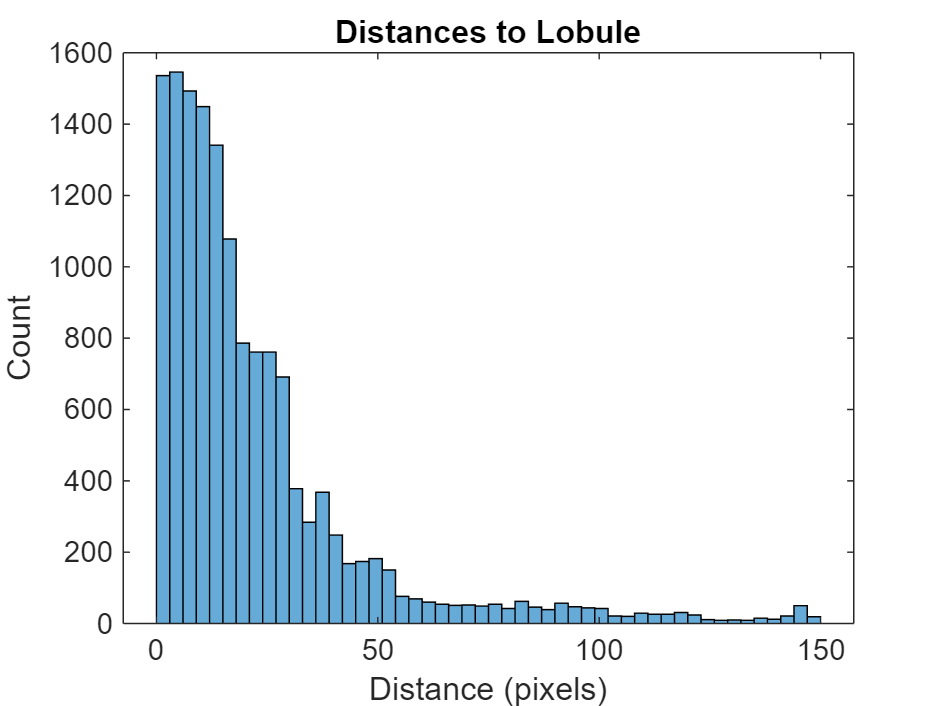

% rough skel_p
skel_p = bwskel(logical(portal),'MinBranchLength', 100);

% Distance from skel_pruned_p to lobule_dilate_new
D_lobule = bwdist(voronoi_boundaries_filtered);
distances_to_lobule = D_lobule(skel_p);

% Distance from skel_pruned_p to central
D_central = bwdist(central);
distances_to_central = D_central(skel_p);

% ratio
distances_ratio = 1 - (distances_to_lobule ./ (distances_to_lobule + distances_to_central));

% Basic statistics
stats = struct();

stats.mean_dist_lobule = mean_dist_lobule;
stats.max_dist_lobule = max_dist_lobule;
stats.std_dist_lobule = std_dist_lobule;

stats.mean_dist_central = mean_dist_central;
stats.max_dist_central = max_dist_central;
stats.std_dist_central = std_dist_central;

stats.mean_dist_ratio = mean_dist_ratio;
stats.max_dist_ratio = max_dist_ratio;
stats.std_dist_ratio = std_dist_ratio;

% Add percentiles
stats.p25_lobule = prctile(distances_to_lobule, 25);
stats.p50_lobule = median(distances_to_lobule);
stats.p75_lobule = prctile(distances_to_lobule, 75);
stats.iqr_lobule = iqr(distances_to_lobule);

stats.p25_central = prctile(distances_to_central, 25);
stats.p50_central = median(distances_to_central);
stats.p75_central = prctile(distances_to_central, 75);
stats.iqr_central = iqr(distances_to_central);

stats.p25_ratio = prctile(distances_ratio, 25);
stats.p50_ratio = median(distances_ratio);
stats.p75_ratio = prctile(distances_ratio, 75);
stats.iqr_ratio = iqr(distances_ratio);

statsTable = struct2table(stats);
writetable(statsTable, 'voronoi statistics.csv');

% Visualize distributions
figure;
histogram(distances_to_lobule);
title('Distances to Lobule');
xlabel('Distance (pixels)');
ylabel('Count');
saveas(gcf, 'distance to lobule.png')

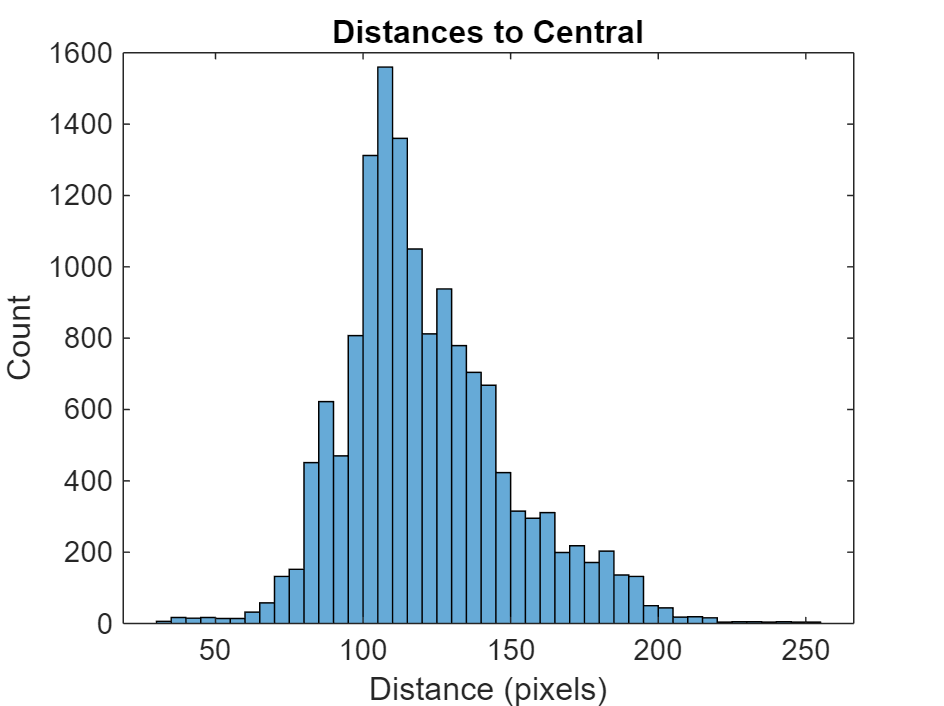


figure;
histogram(distances_to_central);
title('Distances to Central');
xlabel('Distance (pixels)');
ylabel('Count');
saveas(gcf, 'distance to central.png')

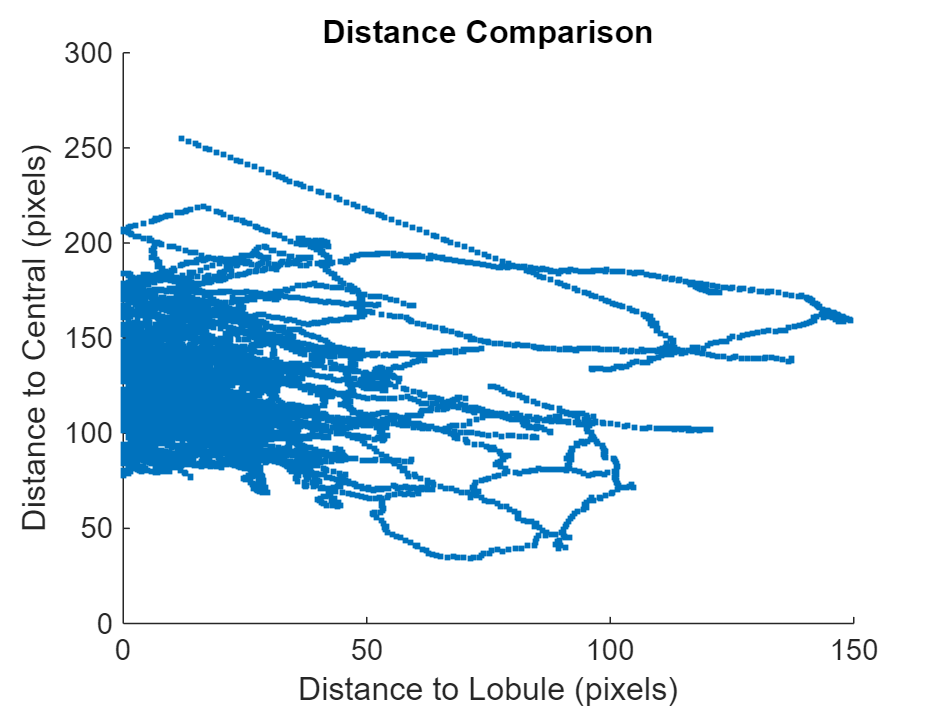


figure;
scatter(distances_to_lobule, distances_to_central, '.');
title('Distance Comparison');
xlabel('Distance to Lobule (pixels)');
ylabel('Distance to Central (pixels)');
saveas(gcf, 'distance comparison.png')

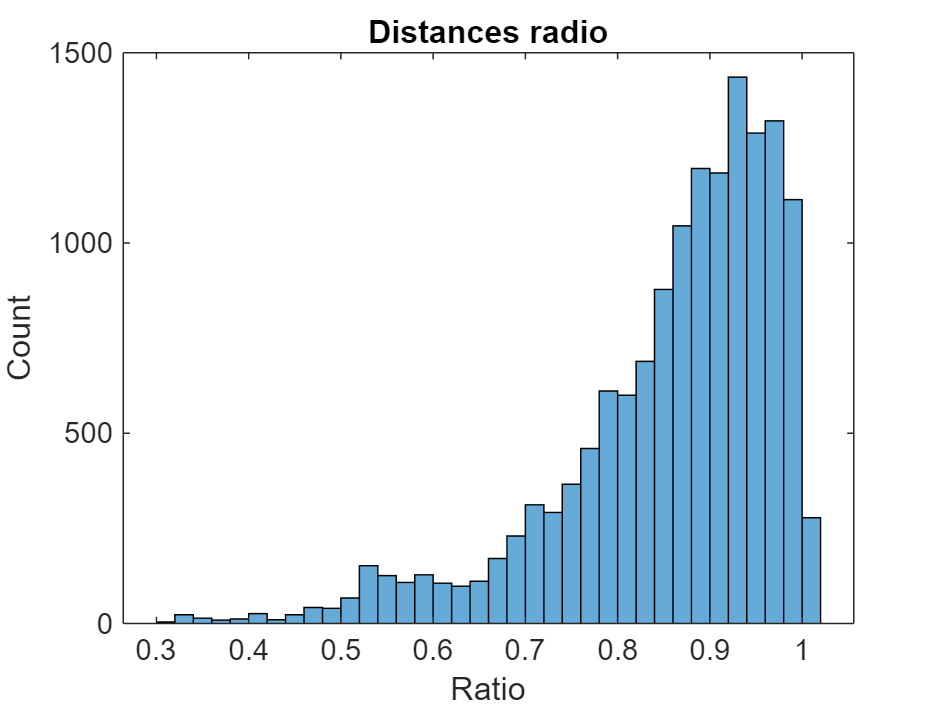


figure;
histogram(distances_ratio);
title('Distances radio');
xlabel('Ratio');
ylabel('Count');
saveas(gcf, 'distance ratio.png')